## Communications Project Report 1

### Isaac Eitan

Pauli Murray College, 2025

#### Goal: To design and verify a communication system that transmits in the presence of cosmic background noise MNIST images from Mars to Earth as intelligible images using the minimum total signal energy. The image quality is determined by the application system, for example, as part of a resume for job orgraduate school.

Notes: 

- The bulk of the report will be your narratives explaining what the code snippets do and your analysis of the results in the context. To reduce the degrees of freedom (effort) in the project, it is suggested that you transmit binary images and use bit repetition for error correction, unless you want to try to design another system.

- Code snippets should replace "x=input()" statements with "x=" the value you used in the code. This will make the .mlx run without any input requests.

- The final project is submitted as a .zip file that contains this .mlx file plus and .m files referenced.

- The project due date is Oct 23.

#### Design constraints.

Let $IDN$ be the last 4 digits of your Yale ID number.

Electrical power (battery voltages = $+A_{max}$ and $-A_{max}$):  


$$A_{max} = 3 \log_{10}(IDN)$$


Cosmic radiation noise variance measured at receiver output: 


$$\sigma^2_N = (20\,\log_{10}(IDN))^2$$


Maximum bit error probability for intelligible images determined by.


$$PE_{max}= \min(\sqrt{IDN/1000}/10,0.15)$$


The following is the code snippet that computes these values, after you inset your IDN and PE_max values..

clear
clc
IDN = 8340  % replace with your IDN last four digits of Yale ID number.

IDN = 8340

rng(IDN) % set random number generator seed
var_N = (20*log10(IDN))^2

var_N = 6.1502e+03

sigma_N = sqrt(var_N)

sigma_N = 78.4233

Amax = 3*log10(IDN)

Amax = 11.7635

PE_max = min([sqrt(IDN/1000)/10,0.15]) % replace IDN with the last 4 digits of your Yale ID number

PE_max = 0.1500

## Desired application

*Your are designing a system to achieve a partcular perceptual quality. Describe the application that you have in mind that motivates your choice for your image quality:*

A robot that takes pictures of different shapes found in the surface of Mars and then transforms it to a black and white picture highlighting the shape form in a 28x28 grid (through signal processing techniques); then, the final image is transmitted to Earth. Since the main idea of the scientists is to see the shape not the specific details, the quality of the image needs to be enough for the scientints to extract the "original" shape. This means that images need to be clear but not extremely clear, so perhaps they can even have errors at less than 7.5 %, as we see in one of the demos. Of course, if the MNIST images can be send in an efficient way with not a lot of errors, we could use the same designed system but changing the binary image digits. 

## Extract MNIST and display images of IDN 

Include your narrative that explains what this code does.

Narrative: This code shows the images that we want to transmit.

In the first block of code, MATLAB loads the MNIST data base and stores it into a variable called DB. Then, to understand the data set's size, we learn that it has 10 thousand images (rows), each with 784 pixels (since each image is 28x28) and an extra pixel that correponds to the label of that image (corresponding to columns).

In the second block the variable mymnist is initialized to a 4x785 array filled with 0's. Why this number? Well, from above we know that the rows represent the number of images and columns the number of pixels; in this case, there are 4 images and same amount of pixels. Moreover, it is initialized to 0 so that the following for loop can store the image information in mymnist. The for loop basically looks through the MNIST DB to get the IDN digits, which are stored in val, and then plots it. Inside the big for loop (which loops 4 times) has another for loop that goes from 1 to 1000 in the MNIST DB to get the information from the digits in val. Once it found the desired digit, and stores the information in mymnist, the loop breaks and prepares to plot in one spot of a 4 grid to display digit images, it reshapes the data into  28x28 form (storing that into digIm), and then digIm is transposed, the color map is selected to be gray, and the images are displayed using imagesc(). Now, this is repeated 4 times--1 time for each of the digits.

load('mnistb_test.mat')  % load binary MNIST digits
DB = mnistb_test;
[rows cols] = size(DB)

rows = 10000

cols = 785

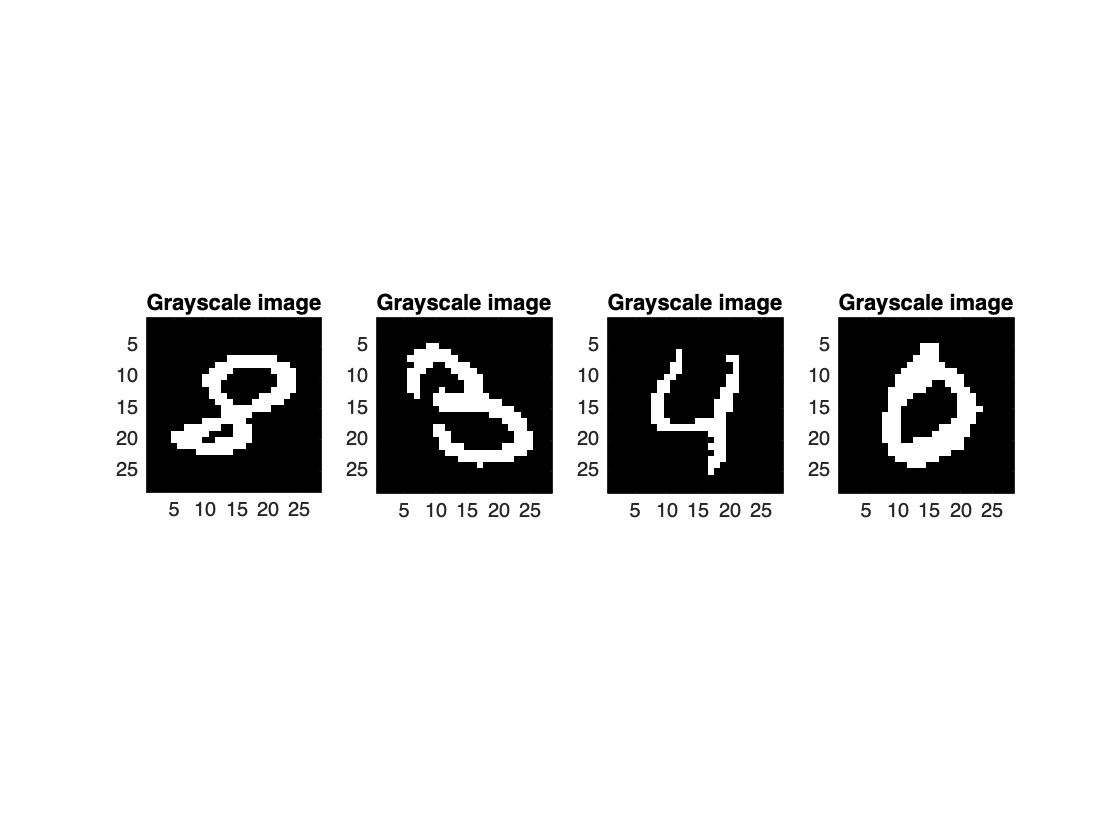

mymnist = uint8(zeros(4,785)); % array stores four images
% IDN = 8340 
val = [8 3 4 0]; % replace with an array containing your digits
for num = 1:4
    for numseek = 1:1000 % examine the MNIST DB to find your digits
        if DB(numseek,1) == val(num)  % mnist label = IDN(num)
            mymnist(num,:) = DB(numseek,:);
            break % terminate search loop
        end
    end
    subplot(1,4,num)
    digIm = reshape(mymnist(num,2:785),[28,28]); % form the original 28x28 image
    digIm = digIm'; colormap(gray); imagesc(digIm); axis image; title('Grayscale image')
end

## Form DT of transmitted images.

Narrative: DT is data transmission. In other words, the images that we want to transmit (the ones above) need to be digitally represented in order to be transmitted. To do this, the program converts the pixel values of the images into binary data to then arrange the data sequentially (put the binary data in a bitstream). This is what the code is doing.

DB is renamed to only store the data that we want (the one needed to display the 4 digits, or mymnist). Then, we create an array called DT, which basically works to store the pixels in one image; the times 4 means each pixel will be represented by 4 bits.

The pointer pDT will be used to track the current index in the DT array where the next bit value should be stored.

DB = mymnist;  % from the previous section
[nImages,cols] = size(DB);
nFeatures = cols-1;  
DT = zeros(1, 4*nFeatures); % preallocated array for transmitted bits
pDT = 1; % pointer to DT array
for row = 1:nImages
    x = DB(row,2:nFeatures+1);
    for column = 1:nFeatures
        bit = x(column);
        DT(pDT) = bit; 
        pDT = pDT+1;
    end
end

- What is the variable x in this section?

- Answer: x is a row vector that contains only the pixel values (not the label pixel--8, 3, 4, or, 0--which is why the the range expressions starts from 2) of the image in which the loop is going through (it could the image 1, 2, 3, or 4, corresponding to the digits in val). In short, x contains the pixel values, in row form, of one of the images. Note that x is different for every image.

- What is the purpose of the column for loop?

- Answer: The purpose is to go through all the pixel values (for each image) and store them in DT. First, the the program selects--in order--the corresponding (to column) pixel value of a certain image from x and names it bit. Then, that bit is assigned to the position in DT corresponding to the pointer pDT. Iterating over all rows and storing every pixel value in DT forms all of DT. Note that DT is in binary since the images are either black or white.

#### Form DR errors with $PE=PE_{max}$ .

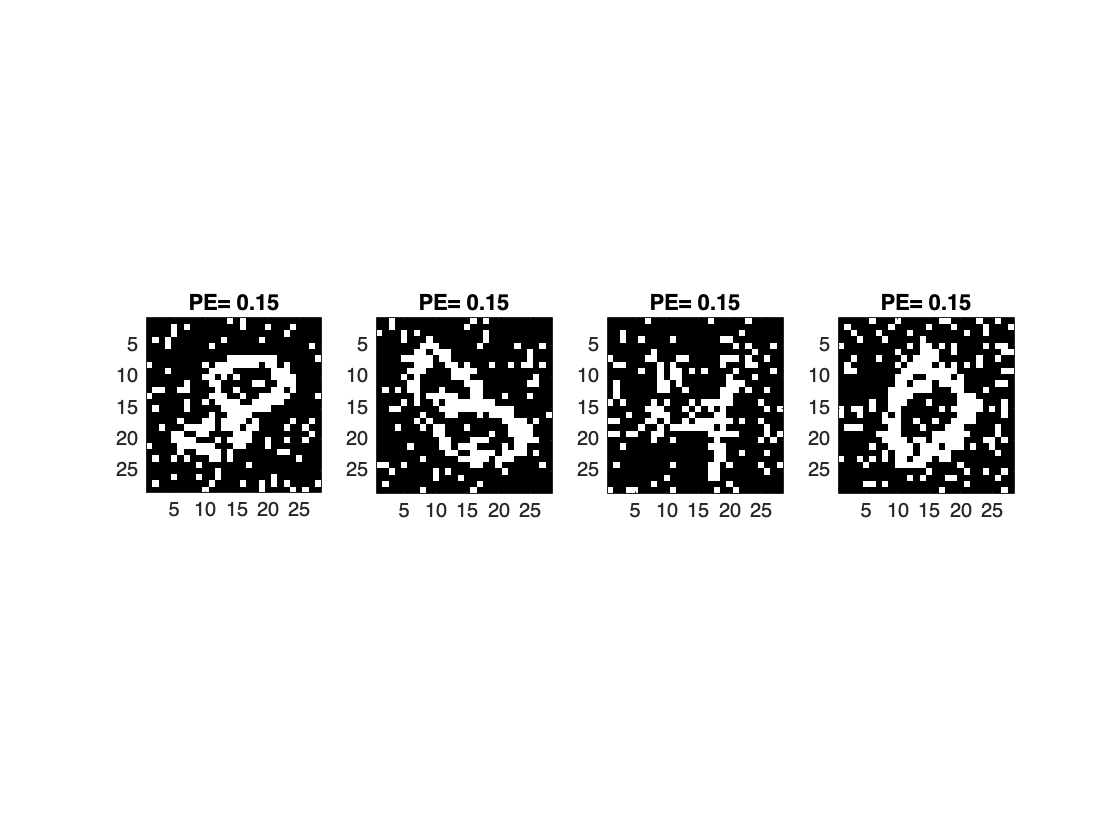

PE = PE_max;
DR = DT; % make copy
for n = 1:length(DR) 
    if rand() < PE
        DR(n) = xor(1,DR(n)); 
    end
end
% verify 
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im');colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

- Explain how the xor() function forms errors.

- ANSWER: First, the xor() function is activated only if the output of rand(), which is uniformly ouputs a number in the range (0, 1) like probability, is below PE_max. This guarantees that the number of flipped bits does not exceed PE_max. If rand() < PE_max, then the xor() function will form errors by flipping bits. Usual XOR functions have two binary inputs--say A and B--and one binary output--Y. In this case, A is already set to 1 and B = DR(n). XOR's truth table states that if DR(n) = 0, then Y = 1. If DR(n) = 1, then Y = 0. So, once rand() < PE_max, no matter what bit value is in DR(n), it will be flipped. In other words, a bit in DR is flipped with probability of PE = PE_max.

- Explain how the DR bit sequence forms images.

- ANSWER: The DR sequence is the DT sequence but with having errors with a probability of PE. So, the new sequence exists. How is that sequence transformed so that it can be plotted? In the second for loop we can see the process. For every image the program uses the reshape() function to store the data that can be plotted in Im. The first input of reshape() is the pixels corresponding to each image: for each nth image, the corresponding pixels in DR range from 784*(n-1)+1:784*n. The second input of reshape() is the size we want to accomodate in the select pixels, which in this case is 48x48 (as are the original MNIST images). Then, the image matrix Im is converted to a uint8--unsigned integer data type that can only represent values from 0 to 255--matrix (in this case, if for some reason an entry in Im is a decimal, it will be rounded to nearest integer). Also, the uint8 data type is an easy to store and transmit data type.

- To justify your value of $PE_{max}$ copy this section code and paste it twice below in separate sections to form DR2 and DR3 sequences, where DR2 is formed with $PE = 2PE_{max}$ and DR3 is formed with $PE=\frac{PE_{max}}{2}$. (Change the DR to DR2 or DR3 in all the required code).

- Answer: Done.

- Comment on the quality of the images formed by DR2 and DR3.

- Asnwer: DR2 has way worst quality than DR3. This makes sense since PE for DR2 is greater than for DR3, which in turn causes the xor() function in DR2 to flip more bits since it is more likely than it will get activated than in the code for DR3. This is why the PE value matters: if it's too high, then the image is unreadable (as in DR2). DR3 looks almost as perfect, and better than DR, yes; but, at least DR is readable. 

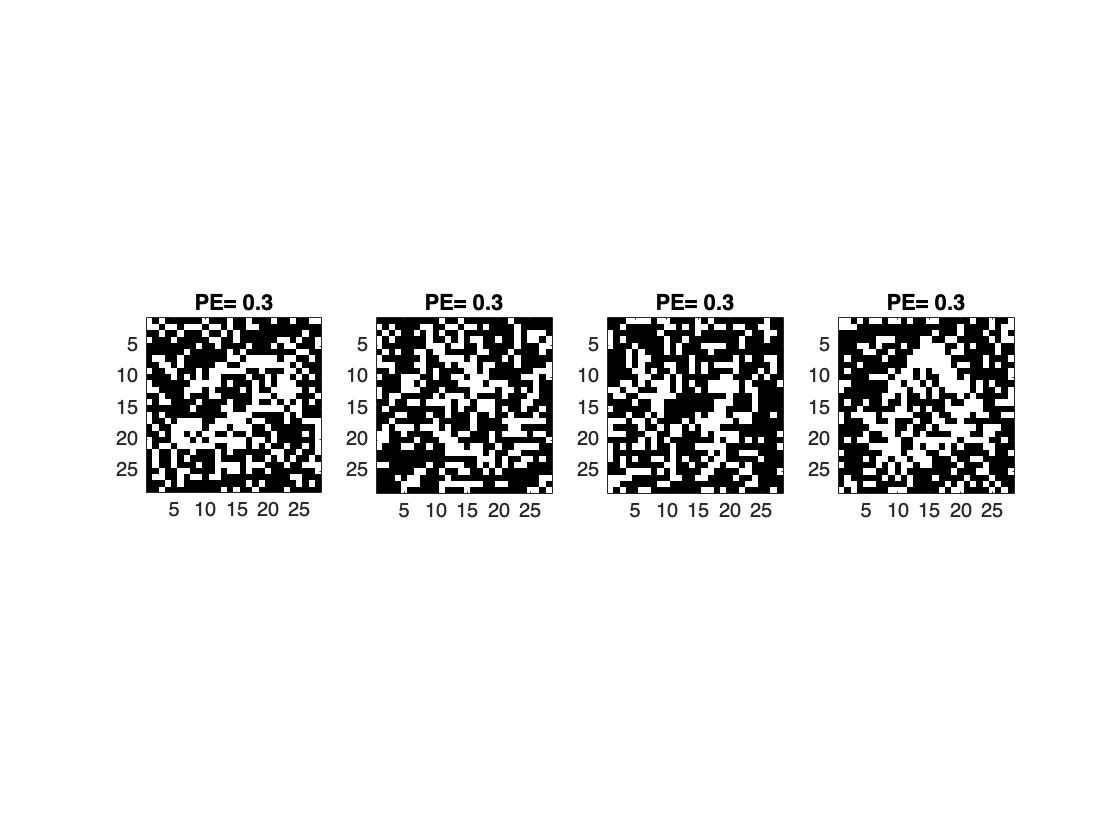

%DR2
PE = 2*PE_max;
DR = DT; % make copy
for n = 1:length(DR) 
    if rand() < PE
        DR(n) = xor(1,DR(n)); 
    end
end
% verify 
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im');colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

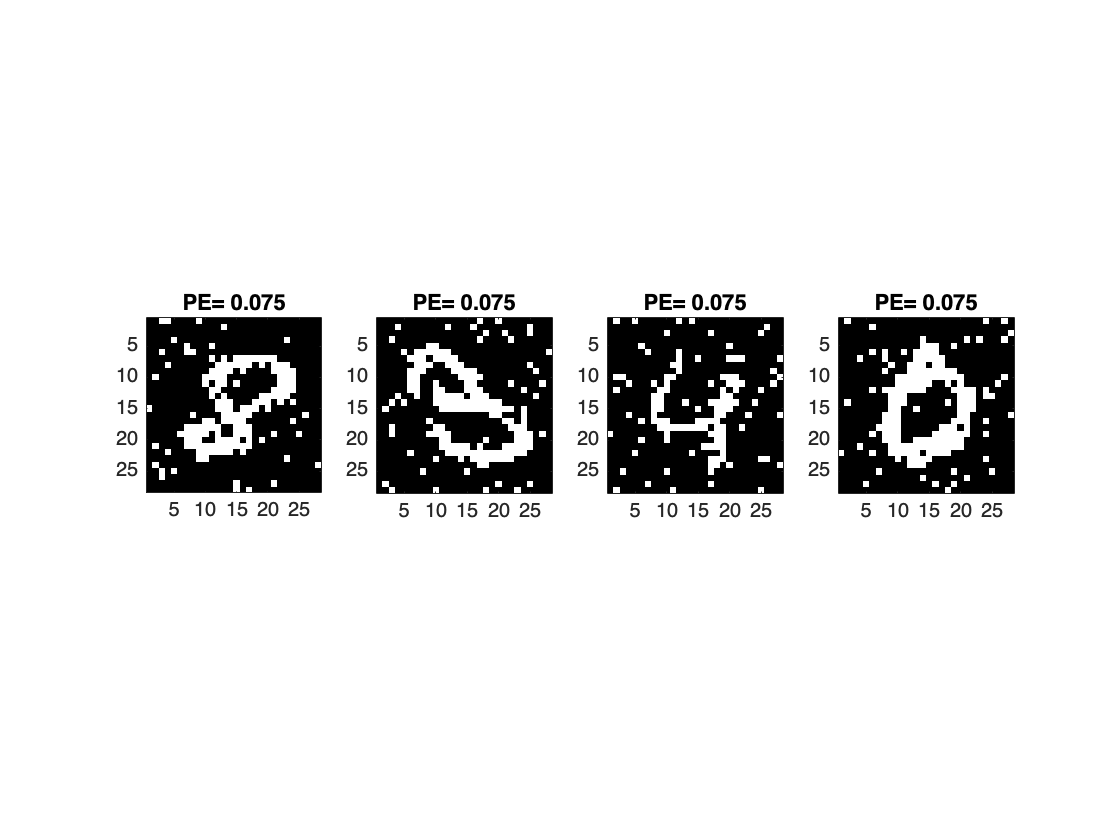

%DR3
PE = 0.5*PE_max;
DR = DT; % make copy
for n = 1:length(DR) 
    if rand() < PE
        DR(n) = xor(1,DR(n)); 
    end
end
% verify 
NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im');colormap('gray');axis image;drawnow
    title(['PE= ' num2str(PE)])
end

## Simulating a communication system.

#### Design prototype signal.

Compose code snippet setting to form and display a trial prototype signal to transmit bits in the communication channel.

The example in the following is a sin wave with two periods during the signal length $N_{sig}$ = 40. Please design a different signal with the same maximum and minimum amplitudes $+A_{max}$ and $-A_{max}$.

%{
clf % 
format compact;
%Example of the designed signal. Please design a different signal
Nsig = 40; % Signal Length
t = 0:Nsig-1; % Nsig-1 as engineers start at 0
numPeriods = 2;
s = Amax*cos(2*pi*numPeriods*t/(max(t)+1)); % creating a sinusoidal signal of length 40.
%Plot the signal
stem(t,s)
hold on
plot(t,s)
hold off
grid on
title('Prototype Signal S')
xlabel('Time')
ylabel('Amplitude')
%}

% New signal: Binary signal
clf % 
format compact;

Nsig = 80; % Signal Length
t = 0:Nsig-1; % Nsig-1 as engineers start at 0
numPeriods = 1;

%To plot this signal, one requires the "Signal Processing Tool Box"
s = Amax*square(2*pi*numPeriods*t/(max(t)+1)); % creating a sinusoidal signal of length 40.

%Plot the signal
stem(t,s)
hold on
plot(t,s)
hold off
grid on
title('Prototype Signal S')
xlabel('Time')
ylabel('Amplitude')

- **Why did you choose this signal type? **

- **Answer: **If we are transmitting images from Mars, that means the communication system must transmit through cosmic background noise and through very long distance (were the will be attenuated). This said, since we have no control over the noise, the probability of error will be reduced by increasing the energy of the signal as much as possible. A greater energy would also imply a higher signal to noise ratio (SNR) than the sinusoid wave presented. This could be done in three ways: (1) increasing the amplitude, (2) forming binary signals, and (3) increasing the length of the signal. (1) is not possible since the maximum and minimum amplitudes are already $+A_{max}$ and $-A_{max}$. (2) and (3) we could do. Let's do (2), which will have an energy of $n_{x}A_{max}^2$, and also do (3), and see if the signal has a better performance as the project moves on. Even though this is not necessary, since we see that an N_sig of 46 also works, it shows that even though the initial signal we thought of used an Nsig of 80, the constraints could also be fulfilled with a lesser signal duration. Of course, it is important to note that increasing the length comes at the expense of the transmission time.

#### Determine the minimum SNR that produces $PE \leq PE_{max{$. 

The following code estimates the $PE$ value by varying the signal to noise ratio SNR = $E_s/\sigma^2_N$ and simulating DT bit transmissions by adding noise with variance $\sigma^2_N$.

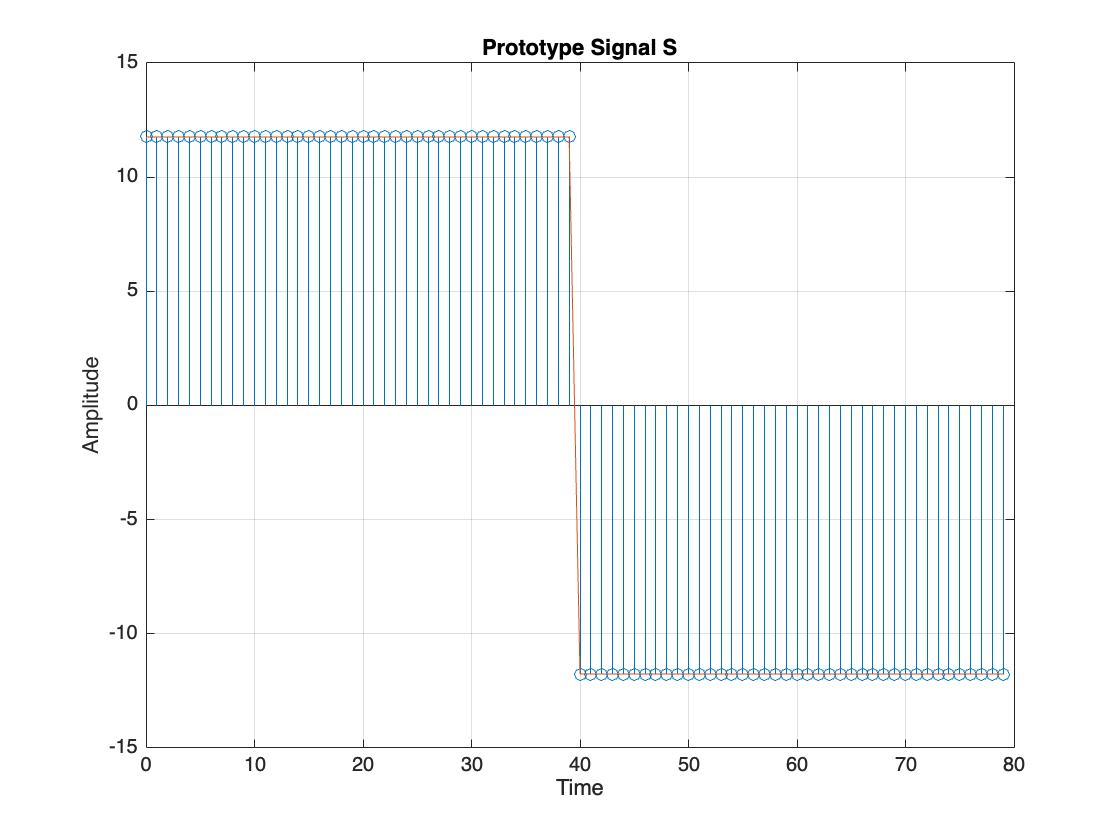

T = s;
Es = round(sum(s.^2));
Nval = 100; PE = zeros(1,Nval); SNR = zeros(1,Nval);
Nbits = length(DT);
for n = 1:Nval
    SNR(n) = (n/40)^2;

    sigN = sqrt(Es/SNR(n)); % set up sigma_N 
    
    Nerr = 0; % initialize count to 0
    for i = 1:Nbits
        sT = s;
        if DT(i) == 0
            sT = -s;
        end
        G = sigN *randn(size(sT)); % Create Gaussian Noise with mean 0 and variance sigN^2
        SR = sT + G;
        V = sum(T.*SR); % Compute the output V of the matched processor
        if V < 0
            DR = 0;
        else
            DR = 1;
        end
        if DR ~= DT(i)
            Nerr = Nerr +1; % Compute the number of errors
        end
    end
    PE(n) = Nerr/Nbits; % Compute the estimated PE for the corresponding SNR
end
semilogy(SNR,PE)
hold on
semilogy(SNR,PE,'o');grid on;xlabel('SNR = E_s/\sigma^2_N');ylabel('PE');xlim([0 5]);hold off;

        The plot can be examined more closely by clicking on the + looking glass icon above the plot and placing  cursor over data circle to     reveal values. Rerun the section code to reset the plot if needed. Find the SNR value from the linear interpolation between points

- **Find the SNR value make the PE be closest to **$PE_{max}$? 

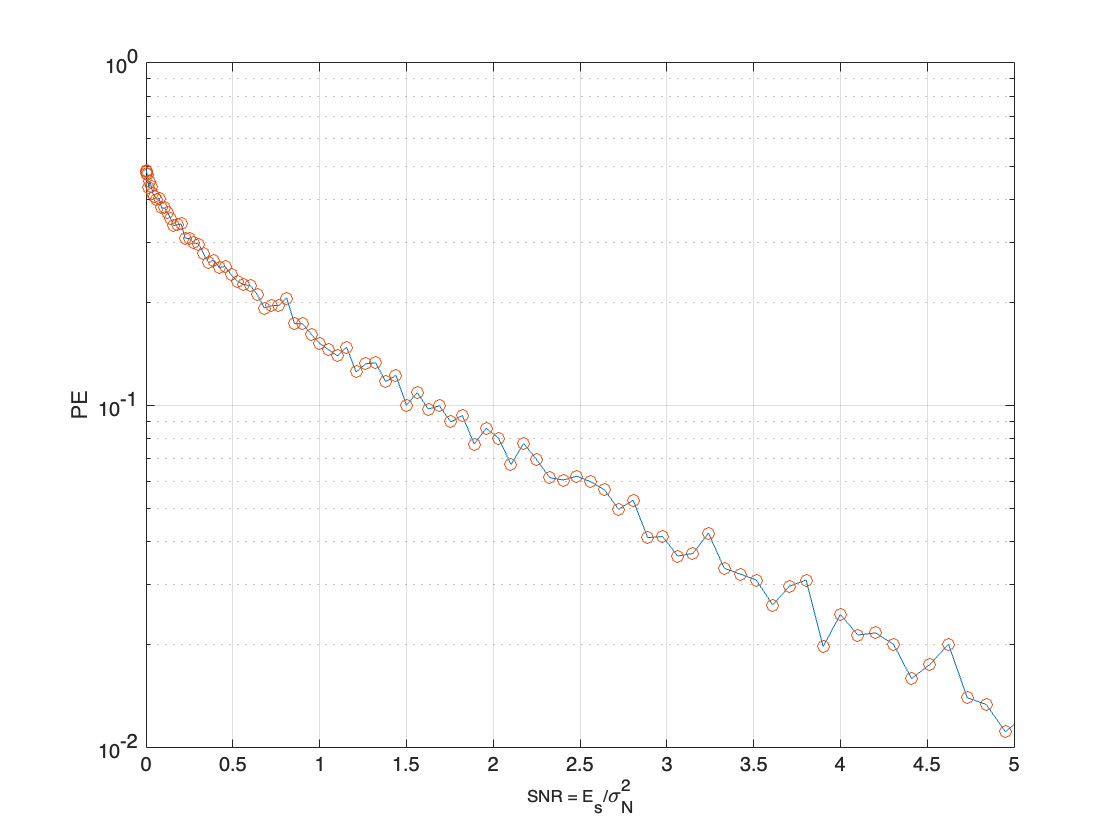

%Write a code and explain how do you find the SNR_PEmax.

% Explanation: We first compute a row vector abs(PE-PE_max) which has all
% the possible differences between PE_max and all possible values of PE
% plotted above. Then, the code finds the minimum difference and outputs
% its value ('difference') and its 'index'. Since there is a one to one
% correspondence between PE and SNR, one just outputs the SNR value
% corresponding to given index to find SNR_PEmax.


[difference, index] = min(abs(PE-PE_max));
SNR_PEmax = SNR(index)

        2.  **What value of signal energy **$E_{s,min}$** that achieves your **$PE_{max}$ **with** $\sigma^2_N = (20\,\log_{10}(IDN))^2$** computed earlier? **

- **Explanation: **We have that $SNR = E_s/\sigma^2_N$. And from the computation above, $SNR_{PEmax} \leq SNR = E_s/\sigma^2_N 	$ since a lower value than  $SNR_{PEmax}$ would make PE be greater than $PE_{max}$. This makes sense since higher values of SNR actually make $E_s$ higher since $\sigma^2_N = (20\,\log_{10}(IDN))^2$ remains the same. Then, it's implied that $SNR_{PEmax}*\sigma^2_N \leq E_s $, and hence $E_{s,min} = SNR_{PEmax}*\sigma^2_N$.

% Write a code to find Es_min. The value below is just an example not the answer. 
Es_min = SNR_PEmax*var_N

#### Compute $N_{sig}$ for the transmission signal so that it is an even number. 

- **Compute a value of **$N_{sig}$** for your prototype signal to make the signal energy bigger than **$E_{s,min}$. 

- **Verify the prototype gives **$E_s>E_{s,min}$**. Otherwise increase **$N_{sig}$** to a greater even-valued number.**

- **Verify that your signal make your SNR>= SNR_PEmax.**

- **Stem plot the protoype signal sT = s.**

- **Stem plot a typical signal in  noise  SR = sT+N.**

%1. The following code use the prototype signal as the example given before. 

SNR_PEmax = 1

% It checks if Es_new > Es_min. If not, it adds 2 to N_sig and tries again.
% Please change the prototype signal to the signal you designed before and answer the questions.
N_sig = 2;
numPeriods = 2;

Es_min = 6.1502e+03

Es_new = 0;
while Es_new < Es_min
    t = 0:N_sig-1;
    s = Amax*square(2*pi*numPeriods*t/(max(t)+1));
    Es_new = round(sum(s.^2));
    if Es_new > Es_min
        break
    end
    N_sig = N_sig +2;

end
%2. Verify Es_new > Es_min
Es_new = round(sum(s.^2));

if Es_new > Es_min
    verify = "true";
else
    verify = "false";
end
verify
%3.Verify Es_min and SNR.
SNR_Verify = Es_new /(sigma_N)^2 ;
if SNR_Verify >= SNR_PEmax
    SNR_VerifyCheck = "true";
else
    SNR_VerifyCheck = "false";
end

verify = "true"

SNR_VerifyCheck
% 4. Stem plot of prototype signal sT = s
% To get an intuition, this would be as if Dt == 1 always. Since we are not
% transmitting and we only want to see the "final" prototype signal, we
% should plot that. Note that what is difference from the previously
% plotted signal is that now the duration of the signal is different.

clf % 

SNR_VerifyCheck = "true"

format compact;

t1 = 0:N_sig-1; % Nsig-1 as engineers start at 0
numPeriods1 = 1;

%To plot this signal, one requires the "Signal Processing Tool Box"
s = Amax*square(2*pi*numPeriods1*t1/(max(t1)+1)); 

%Plot the signal
stem(t,s)
hold on
plot(t,s)
hold off
grid on
title('Prototype Signal sT = S')
xlabel('Time')
ylabel('Amplitude')

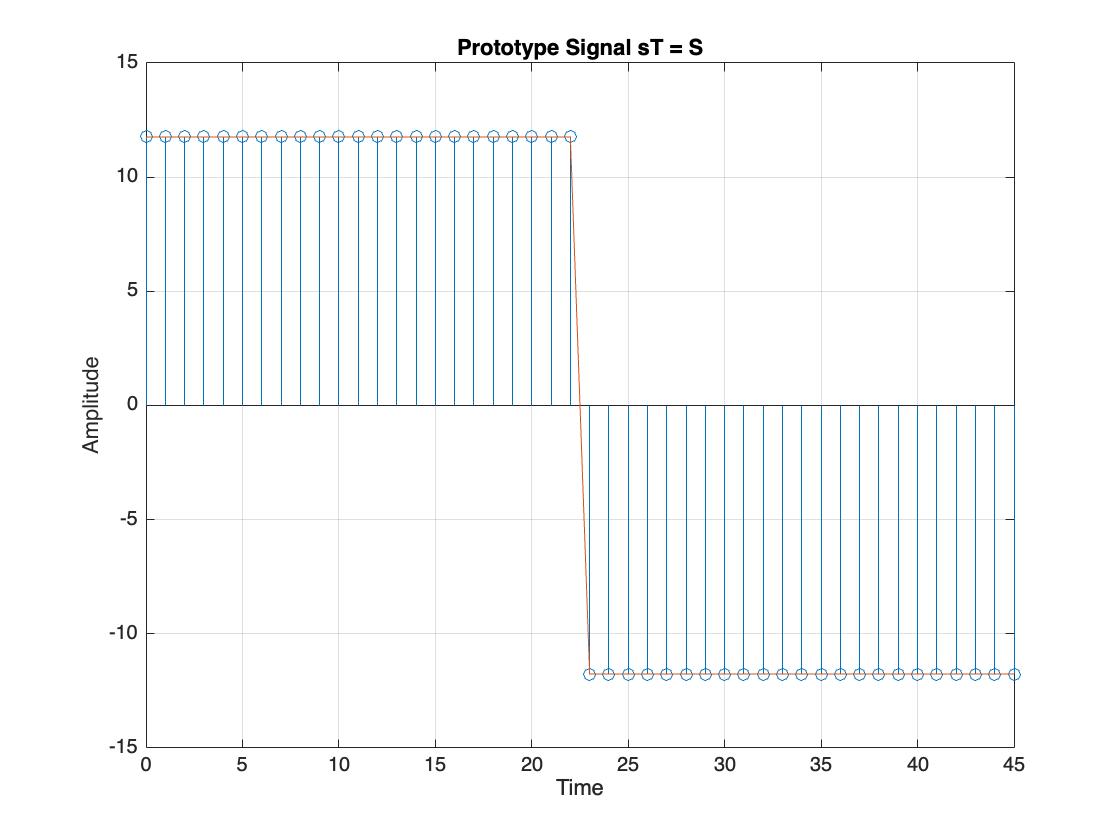

% 5. Stem plot of signal received (with noise): SR = sT + N
clf % 
format compact;

%To plot this signal, one requires the "Signal Processing Tool Box"
sR = s + sigma_N*randn(size(s)); % SR = sT + N


%Plot the signal
stem(t,sR)
hold on
%plot(t,sR)
hold off
grid on
title('SR = sT + N')
xlabel('Time')
ylabel('Amplitude')

This output makes sense since the an SNR of 1 is relatively low compared to possible higher SNR's.

### Communication system simulation with final prototype signal $s$.  

The following questions can be answered in the code.

- **Modify the communication system simulation above to use the prototype signal and to produce the simulated Probability of Error **$PE_{sim}$** value.**

- **Verify that **$PE_{sim} \leq PE_{max}$**.**

- **Compute the total energy to transmit the four images **$E_{sig,tot}$**. **

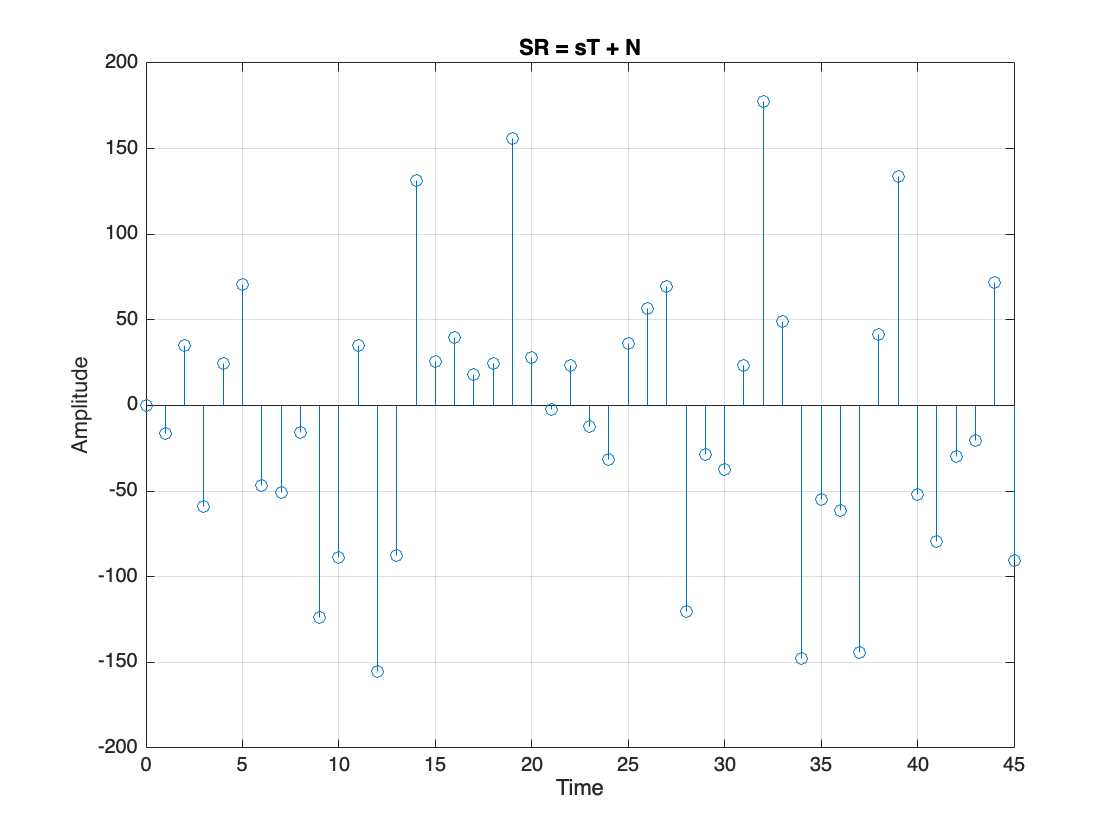

% code - It is wise to display the current values of the important
% paramenters to make sure they have not been changed by previous code
Es = Es_new
N_sig
SNR = SNR_Verify
PE_max
% 1.  Creating  the sT for the 4 images
% This uses a helper function as it will be re-run in the next section.


T = s;
sT = transmitSignal(s,DT);
Nerr = 0;

% creating SR = sT + N
N = sigma_N*randn(size(sT));

Es = 6365

SR = sT + N;

N_sig = 46

SNR = 1.0349

% Estimate PE_sim (Hint: Do the same simulation in the code starting from row 82.)

PE_max = 0.1500


Nbits = length(DT);    
for i = 1:Nbits
        % each bit transmits a complementary signal, and to that signal
        % noise is added. All the signal transmissions are stored in SR (in
        % other words, SR is the concatenation of s1's and s0's plus
        % noise). So, sI gives the transmitted signal plus noise of each
        % bit in DT. 
        sI = SR(length(s)*(i-1)+1:length(s)*i);

        % Why is this done? Because there is an output V for each bit. For
        % instance, T's size is the same size as the signal size (same as
        % sI). But, how many sI's will there be? Well, one for every bit.

        V = sum(T.*sI); % Compute the output V of the matched processor for each bit
        
        if V < 0
            DR = 0;
        else
            DR = 1;
        end
        
        if DR ~= DT(i) % Only activated when there is a mismatch in bits between DR and DT
            Nerr = Nerr +1; % Compute the number of errors
        end
end
PE_sim = Nerr/Nbits
% 2. Verify that PE_sim <= PE_max
if PE_sim <= PE_max
    PE_simVerify = "true";
else
    PE_simVerify = "false";
end
PE_simVerify
% 3. Computing total energy E_sig_tot

% Explanation for formula:
% There is a transmitted signal for each bit. Since we already have the
% energy for each of the used signals, total energy will be total amount of

PE_sim = 0.1486

% bits times energy signal. The noise energy does not affect the used
% energy since it is not energy produced by the system.

E_sig_tot = length(DT)*(Es_new)

% It's important to note that this formula an approximation, for the actual
% energy will depend on other factors: for instance, the channel conditions.

PE_simVerify = "true"

## Error correction with bit repetition

- **Compose a communication system simulation program that incorporates error correction.**

- **What is the method that modifies the original DT  or sT to include repeated bits?**

- **What method interpret the received bit value formed by the values of the detected repeated bits?**

- **Compute error probability using error correction **$PE_{EC}$**. **

- **The program should form DR_EC, the received bit array. **

- **Display the received images from DR_EC.**

- **Compute the total energy to transmit the four images using error correction **$E_{EC,tot}$

**(1) Compose a communication system simulation program that incorporates error correction.**

We will use the "BIT LEVEL ERROR CORRECTION" technique. This means that we will have a data increase factor (DIF) of 3. Two bits will help us detect the error but three bits will help us correct the error based on     the error detechtion.

**(2) What is the method that modifies the original DT  or sT to include repeated bits?**

Now, we write the code to make the bit repetitions and form 3 bit code words to form the data packet. 

**    Method: **use a self-designed helper function (which is by the end of % file).

repetitions = 3; % define the number of repetitions we want for each bit

E_sig_tot = 19960640

DT_rep = repeat_bits(DT, repetitions); % form new sequence with REDUNDANT bits 

% Now, we transmit the repeated signal in the same fashion as we
% transmitted DT before.

%   2.1 Creating  the sT_rep for the 4 images
T_rep = s;
sT_rep = transmitSignal(s,DT_rep);

%   2.2 creating SR_rep = sT_rep + N_rep
N_rep = sigma_N*randn(size(sT_rep));
SR_rep = sT_rep + N_rep;

%   2.3 Fill the DR_rep (DR for the 3-bit code words). Note that this is
%   not the "final" DR. 
Nbits_rep = length(DT_rep);
DR_rep = zeros(1, Nbits_rep);

for i = 1:Nbits_rep
        sI_rep = SR_rep(length(s)*(i-1)+1:length(s)*i); % Complementary signal plus noise for 
                                                        % each bit,

        V = sum(T_rep.*sI_rep); % Compute the output V of the matched processor for each bit
        if V < 0
            DR_rep(i) = 0;
        else
            DR_rep(i) = 1;
        end
end

% An error-correction circuit examines each received 3-bit code word and outputs D_r = D_t even 
% if one error occurs in the code word.


**(3) What method interpret the received bit value formed by the values of the detected repeated bits?**

The idea is to map the sequence DR_rep with dimensions 1x3*Nbits to the sequence DR_corrections = DR_EC with dimensions 1xNbits. If we assume single errors, then for every 3-bit code word in DR_rep we can know what will be the corresponding value in DR_EC. If at least 2 bits in each code word are 1, then the bit will be 1. We can translate this by writing down that if the sum of a code word is more than or equal to 2, then under SEA the DR must be 1, otherwise it will be 0. *Of course, the errors in this case will come in code words that have more than 1 error, since we can't control the noise; but at least there is a higher chance of having a lower PE using this method. *

- **Method: **Go through every three bits in DR_rep, and add it up. Then, if sum is >= 2, the DR_EC value must be 1, otherwise it will be 0. The mapping of DR_rep to DR_corrections will be through the formula $(i+2)/3$. 

*In the following loop, the i's will be 1, 4, 7, 10, 13... Using that % mapping, we'll get 1, 2, 3, 4, 5...*

% Initialize corrected DR binary sequence
DR_corrections = zeros(1, length(DT));

for i = 1:3:length(DR_rep) % each iteration will be over 3 bits
    sum = DR_rep(i) + DR_rep(i + 1) + DR_rep(i + 2); % sum over bits in code words

    % assign the first bit of corrected DR based on the sum.
    if sum >= 2
      DR_corrections((i+2)/3) = 1;
    else
      DR_corrections((i+2)/3) = 0;
    end
end

**(4) Compute error probability using error correction **$PE_{EC}$**. **

% Find errors in sequence
Nerr_corrections = 0;
for i = 1:length(DR_corrections)
    if DR_corrections(i) ~= DT(i)
        Nerr_corrections = Nerr_corrections + 1; % Compute the number of errors
    end
end

% Compute error probability
PE_EC = Nerr_corrections/Nbits

PE_EC = 0.0638

**(5) The program should form DR_EC, the received bit array. **

This is done in point 3 of this section by storing in DR_corrections = DR_EC the assignments.

**(6) Display the received images from DR_EC.**

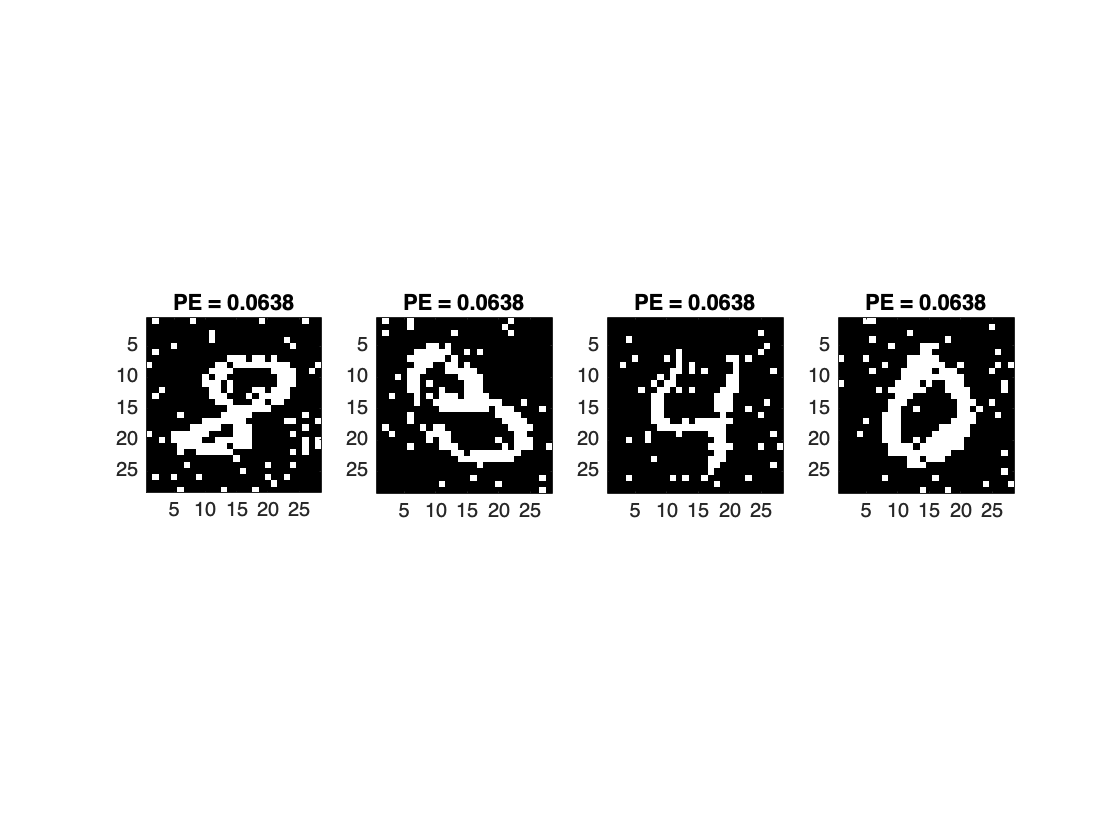

% From above, NumImages = 4;
for n = 1:NumImages
    Im = reshape(DR_corrections(784*(n-1)+1:784*n), [28,28]);
    Im = uint8(Im);
    subplot(1,4,n)
    imagesc(Im');colormap('gray');axis image;drawnow
    title(['PE = ' num2str(round(PE_EC, 4))])
end

**(7) Compute the total energy to transmit the four images using error correction **$E_{EC,tot}$

We will use the same formula used for E_sig_tot with a small difference. We know that energy used comes from the amount of transmitted bits (since transmitting each bit requires us to transmit our designed signal). Accounting for noise, the main difference now is the amount of transmitted bits, which is actually triple the amount of bits in E_sig_tot.

E_ECtot = length(DR_rep)*(Es_new)

E_ECtot = 59881920

## Analyze the final communication system design.

**(1) Compare the values of **$E_{sig,tot}$** and **$E_{EC,tot}$** using reasonable numeric notation.**

- Answer: $E_{sig,tot}<E_{EC}$, or more specifically $3*E_{sig,tot}=E_{EC}$, because the error correction system needs to transmit more bits (in this case, each bit was tripled). It is important to know that this is a known trade-off     (which we'll also mention later), for PE is reduced under the same noise conditions and system contraints but size data is tripled (and so is the energy).

**(2) What, if any, trade-offs were made in your final design. **

- Error correction vs data quantity: As explained above, to correct data *more effectively* the design needs to transmit more data (in this case, triple of the original DT). So, a higher correction rate means a lesser PE AND more transmitted data means more energy used. So, the tradeoff is that to increase improve error correction more redundant data needs to be transmitted; equivalently, to achieve a lesser PE without changing the system constraints (of energy and noise) would require more energy to be used (more energy to be transmitted).

- Signal length ($n_x$) vs data rate: Since there is so much noise from space the data from Mars would require as much energy as possible (which can be done by increasing the signal length). In this case, it's hard to relatively say if our $n_x$ is large or not, but we do know **that it is greater than the one from the original sine-wave shown for the signal**, and it's also a known fact for signal transmitted from Mars. Greater signal lengths mean that the amount of data generated by a source in one second will be lesser.

- Resolution: Since our electrical power is limited, our SNR can't be as large. This means that our PE can't be as low because the signal energy can't increase as much. Then, even though PE has an upper bound, there will still be some errors in the bit transmission. In turn, the errors make the signal understandable but not as good as the original.

**(3) For error correction was there a practical maximum value for the number of repetitions? Why?**

- Yes. I believe this question is to think of further limitations that we may need to consider in out system design, since the answers may vary. 

- When the binary bits are transmitted, they are usually encoded and stored somewhere in the memory or in a buffer; **bus** gets the bits while each signal "asks" for a bit to see if it the system should transmit s_i or -s_i. However, the possible number of adding redundant bits depend on the storage or memory size in the hardware. Perhaps, repeating each bit a 1000 times or doing a data packet error correction may make PE even smaller, but what if the system hardware where the bits are read before transmitting reaches its limit? When that happens we know there will be a maximum value of number of number of repetitions.

- On another note, we could also think of a bandwidth limitation. If the system is transmitting a very large file of data then there could be a network overload and the channel will be more slower than it should be. This could cause trouble if the scientists are expecting the images by a certain time.

**(4) Consultant input: If one change in the system specification could be made, what would it be? How would it improve the system performance? What is the associated hardware increase to the system?**

- **Increase the limitations for the electrical power.** In other words, increase the $A_{max}$ constant. If $A_{max}$ increases, then our final signal design will have a greater minimum energy. A greater signal energy means that there will be a higher SNR, which implies that the noise will not affect as much than with a higher SNR; hence, the probability of error will decrease and better quality images will be received. To accomplish this hardware wise, we could replace the existing battery with a higher voltage battery, or we could more batteries in series with the existing one (making sure the batteries are same capacity and type). However, for the battery increase to work we need to check that the system is compatible to a higher voltage (or voltage of new battery). If the system is not compatible with a higher voltage, then we could replace some components such as capacitors and resistors to make the internal circuit compatible. 

- **Reduce how noise affects the transmission. **One may think that we have no control over the cosmic noise; this is true, but we can add some hardware so that noises affects in a lesser way the transmitted signal. We can add an antenna to the system; this would decrease the level of received noise by focusing the transmission (signal) on a specific direction.

## Summary

**(1) Summarize the steps used to realize the communication system design.**

- The design process requires one to first understand the contraints (since they cannot be changed) and then create the communication system around them. After the constraints are understood, we saw the expected results depending on the probability of error (without transmitting the signals and being affected by noise), merely to comprehend what the goal of the system was. The next important part was to design the signal: to do this, a prototype was created based on the limits of the battery voltage to have a base, but then modifications were made so that the SNR could make PE less than and close to PE_max and so that the signal is above an Es,min (that achieves PE_max with noise)--which is accomplished by changing the signal legnth. Afterwards, a code helped see the effects that noise may have on the transmission, and a processor was used receive the data after the noise effects. After getting the probability of error of the transmitted signal (which was close to PE_max), the *bit level error correction* technique was used.  This method reduced the probability of error in the final received transmission. As a final step, one analyzed the whole system design: one needs to understand the trade-off it has, what can improve and how could it be improved, and its limits.

**(2) Did the system accomplish your expectations for the application. If not, what would need to be changed?**

- Yes since the received images only has an error probability of about 6.4 %. This is whithin the desired quality I stated for the application. In a more general way, the expectations are accomplished since the images are readable and understandable; moreover, one can tell where the error happened and easily reconstruct the original image through further analysis. 

## Helper Functions

function sTh = transmitSignal(s,dt)

s1 = s;
s0 = -s;
t = 0x1;

if dt(1) == 1
    sTh = s1;
else
    sTh = s0;
end

for i = 2:length(dt)

    if dt(i) == 1
        sTh = cat(2,sTh,s1);
    elseif dt(i) == 0
        sTh = cat(2,sTh,s0);
    end
    t = 0:length(sTh)-1;
end
end

% Second helper function creates a binary sequence with the repeated
% number of bits.
function dt_rep = repeat_bits(dt, repetitions)

    % Create a new binary sequence with the desired length.
    dt_rep = zeros(1, length(dt)*repetitions);

    % Iterate over the original binary sequence and repeat each bit (using the repmat() function 
    % in MATLAB) 'repetitions' times.
    for i = 1:length(dt)
        dt_rep(i*repetitions - (repetitions-1):i*repetitions) = repmat(dt(i), 1, repetitions);
    end

end